# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 2ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

## Άσκηση 1

### fir1(.)

#### Χαμηλοπερατό

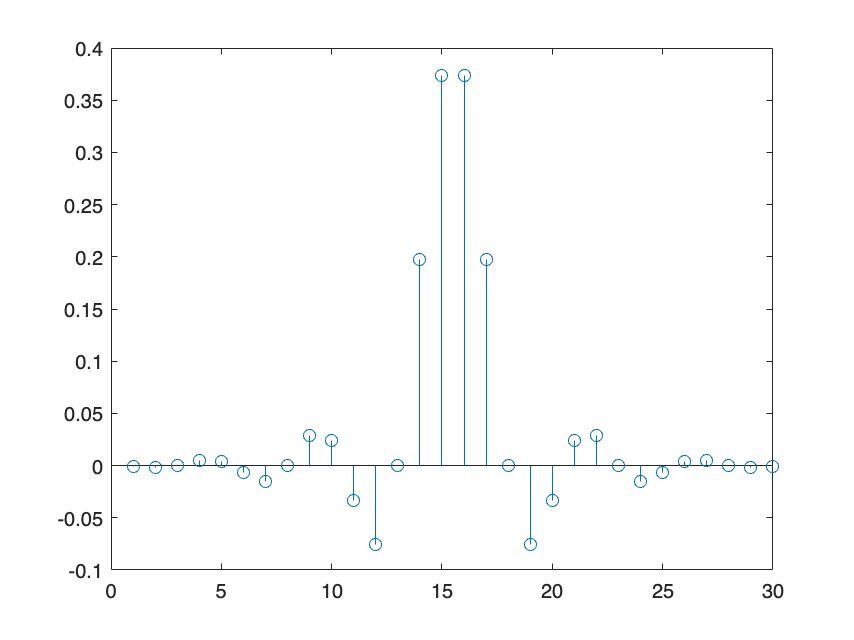

close all;clear;clc;

N = 30;
fc = 0.4;

hc = fir1(N-1,fc,'low');

stem(hc);

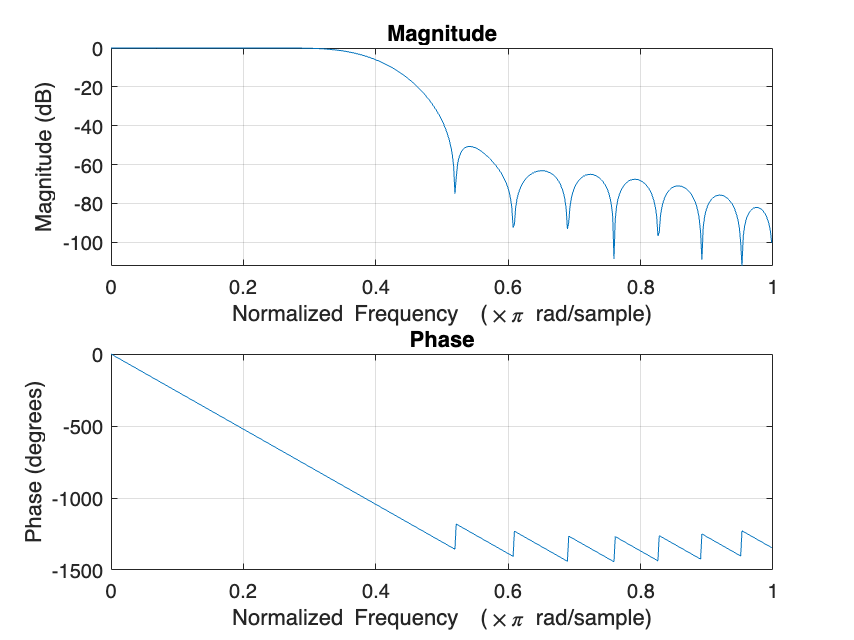


freqz(hc,1,512);

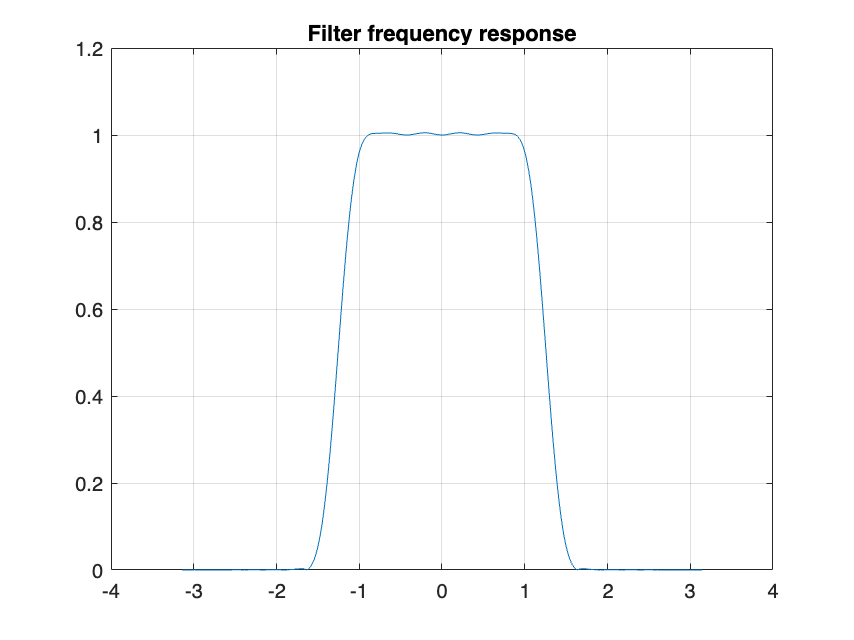


NumFFT = 4096;
Freqs = linspace(-pi,pi,NumFFT);

figure
plot(Freqs, abs(fftshift(fft(hc,NumFFT))));
title('Filter frequency response')
grid on

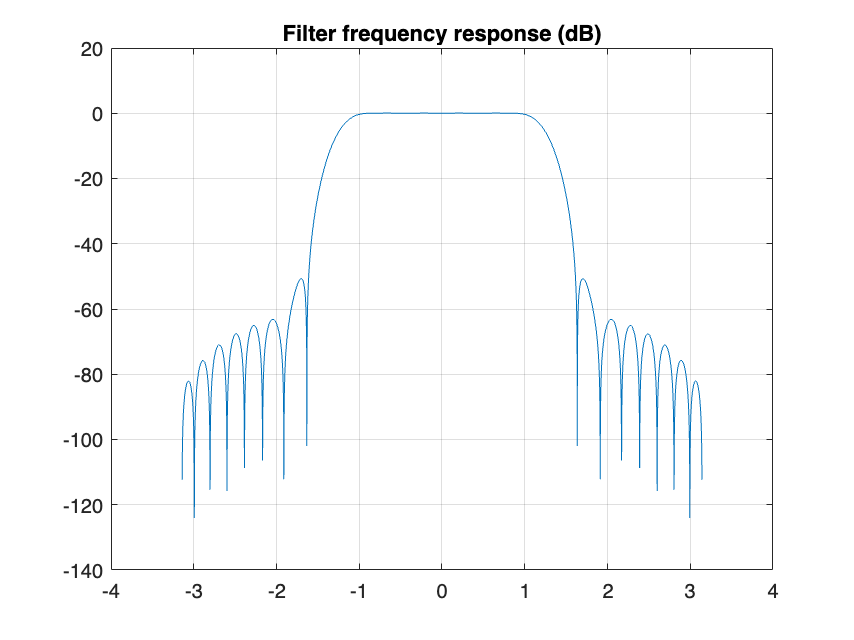


figure
plot(Freqs, 20*log10(abs(fftshift(fft(hc,NumFFT)))));
title('Filter frequency response (dB)')
grid on

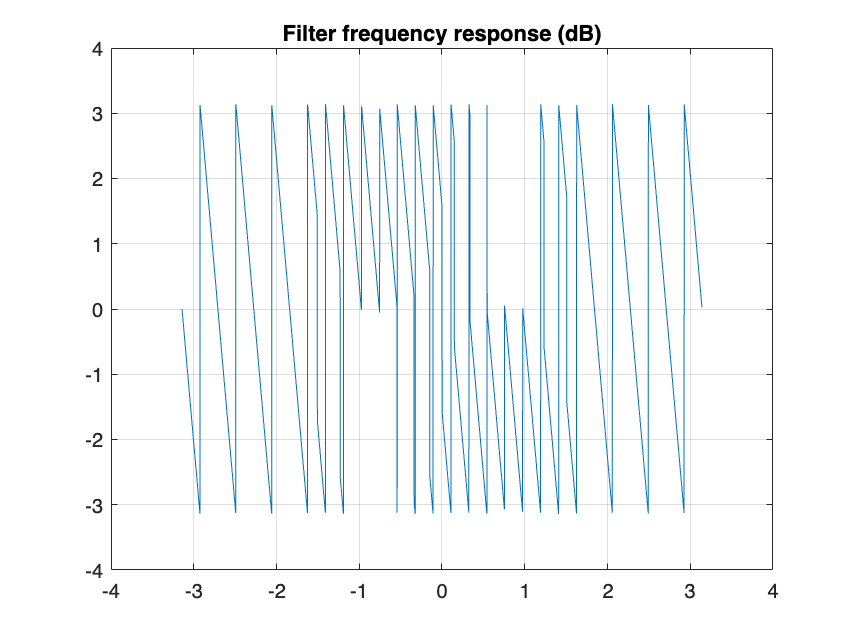


figure
plot(Freqs, angle(fft(hc,NumFFT)));
title('Filter frequency response (dB)')
grid on

#### Υψηπερατό

hc = fir1(N-1,fc,'high');

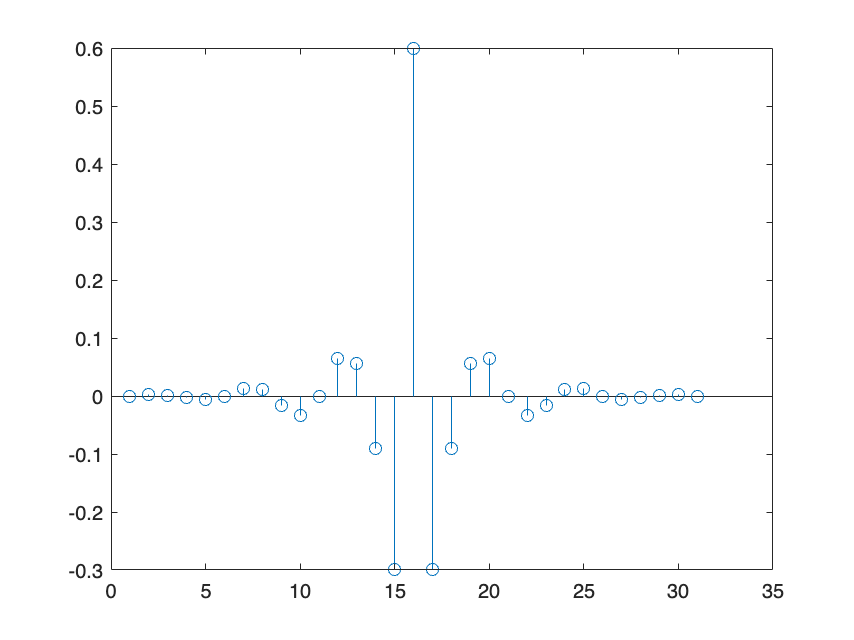


stem(hc);

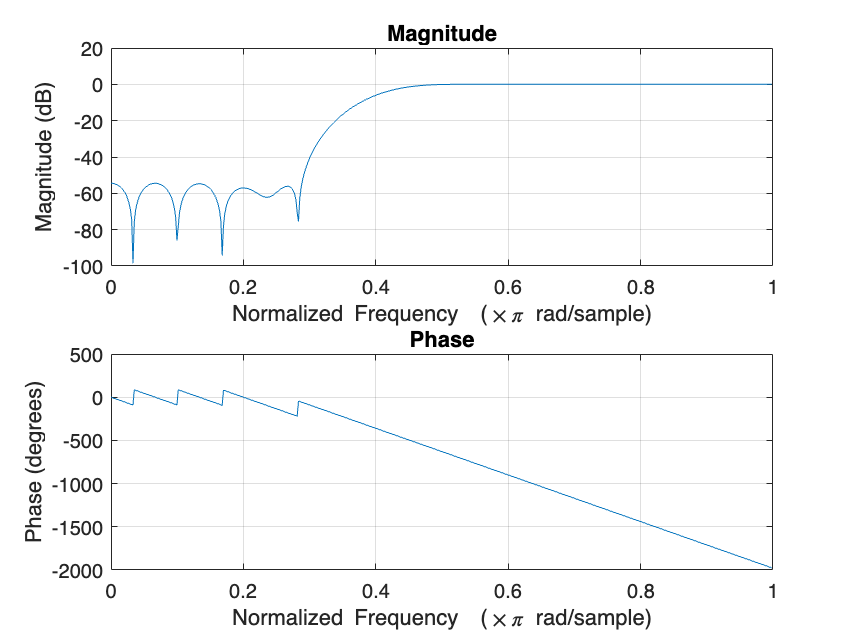


freqz(hc,1,512);

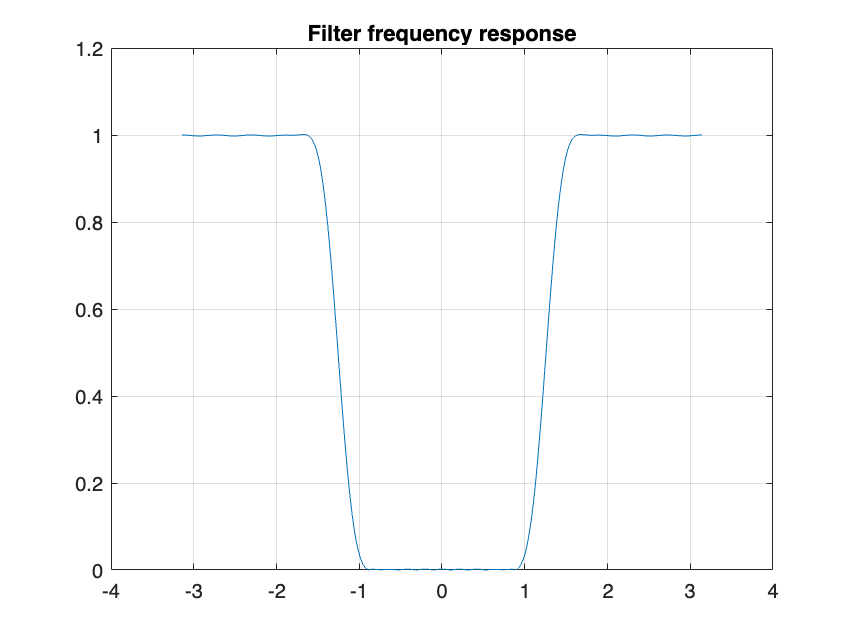


NumFFT = 4096;
Freqs = linspace(-pi,pi,NumFFT);

figure
plot(Freqs, abs(fftshift(fft(hc,NumFFT))));
title('Filter frequency response')
grid on

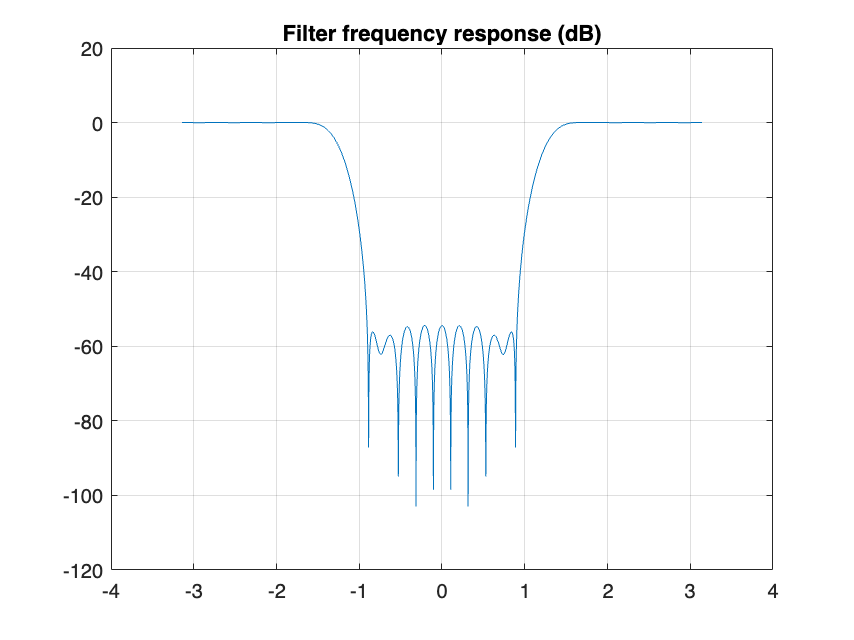


figure
plot(Freqs, 20*log10(abs(fftshift(fft(hc,NumFFT)))));
title('Filter frequency response (dB)')
grid on

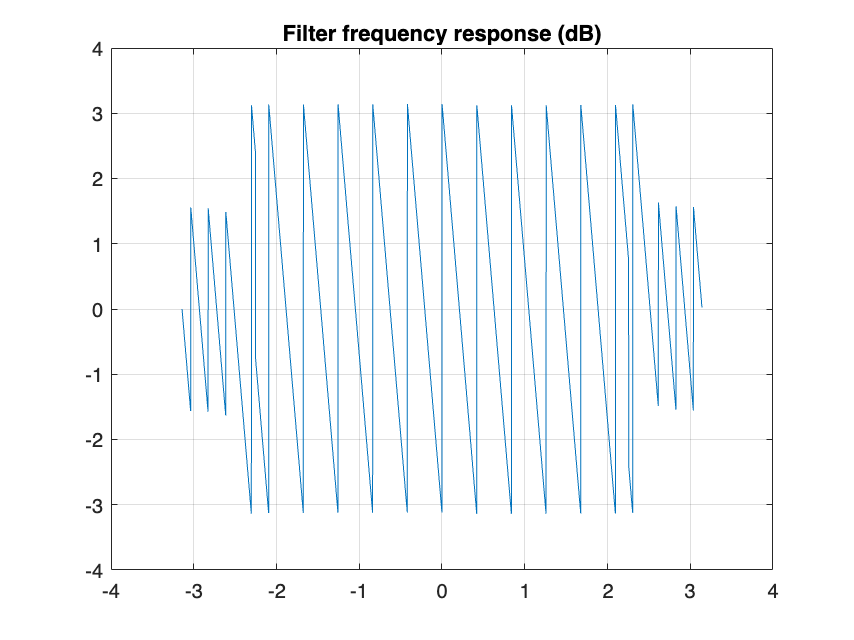


figure
plot(Freqs, angle(fft(hc,NumFFT)));
title('Filter frequency response (dB)')
grid on

### firls(.)

h_low = firls(N-1,[0,0.1, 0.35, 1] , [1 1 0 0]);  %Χαμηλοπερατό
h_high = firls(N-1,[0,0.1, 0.35, 1] , [0 0 1 1]); %Υψηπερατό

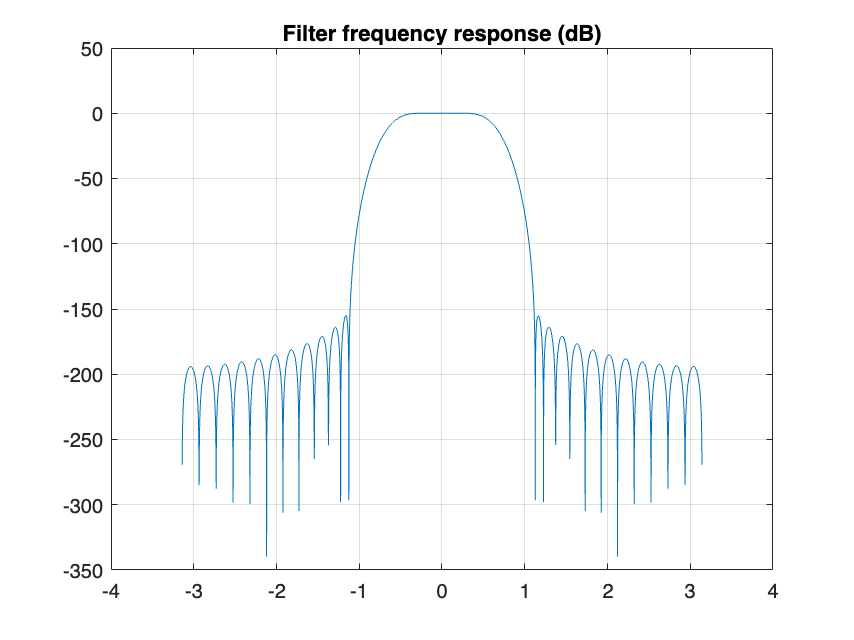


figure
plot(Freqs, 20*log(abs(fftshift(fft(h_low,NumFFT)))));
title('Filter frequency response (dB)')
grid on

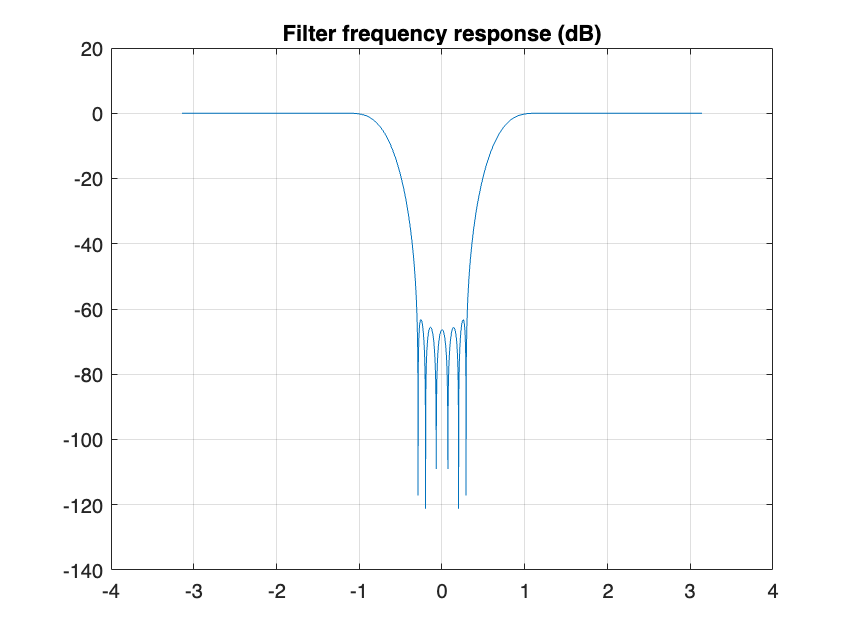


figure
plot(Freqs, 20*log10(abs(fftshift(fft(h_high,NumFFT)))));
title('Filter frequency response (dB)')
grid on

### firpm(.)

h_low = firpm(N-1,[0,0.1, 0.35, 1] , [1 1 0 0]);  %Χαμηλοπερατό
h_high = firpm(N-1,[0,0.1, 0.35, 1] , [0 0 1 1]); %Υψηπερατό

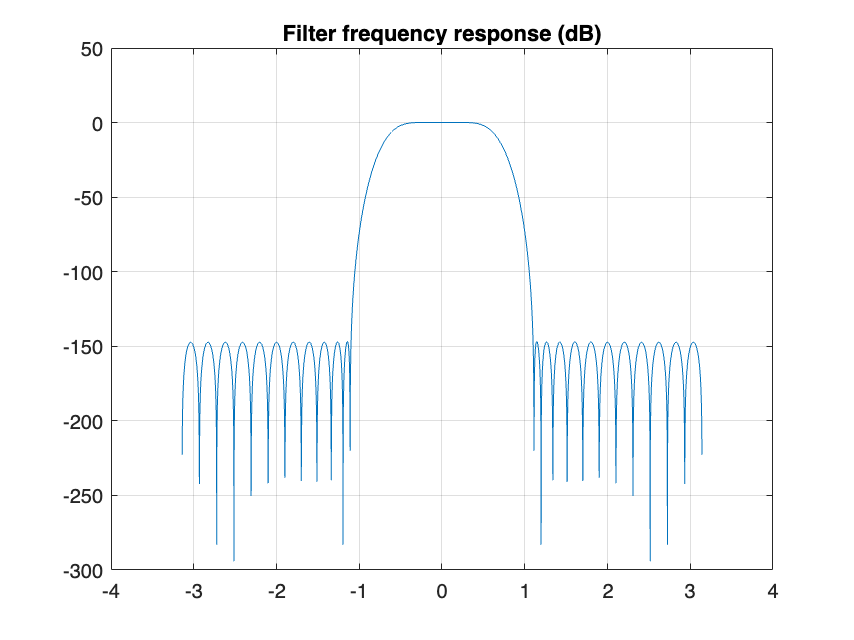


figure
plot(Freqs, 20*log(abs(fftshift(fft(h_low,NumFFT)))));
title('Filter frequency response (dB)')
grid on

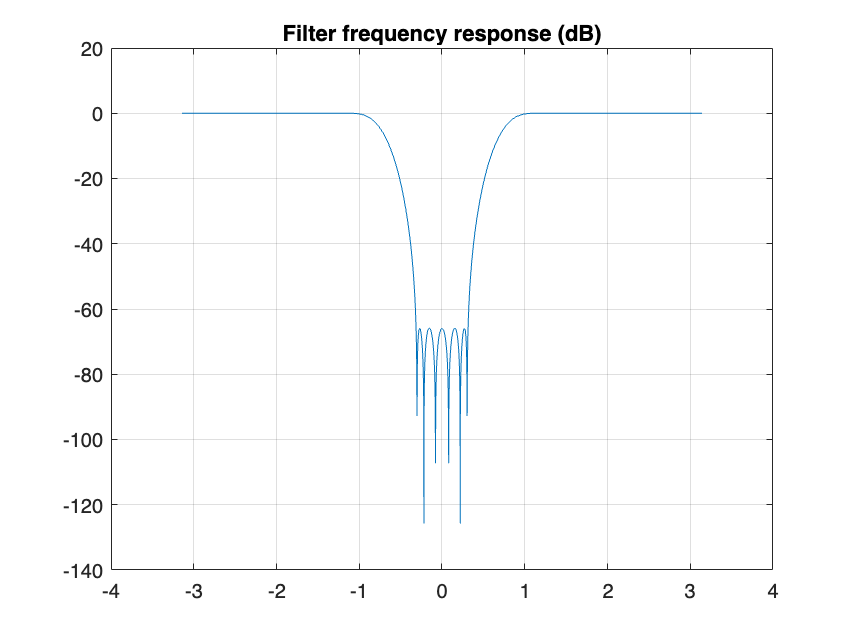


figure
plot(Freqs, 20*log10(abs(fftshift(fft(h_high,NumFFT)))));
title('Filter frequency response (dB)')
grid on

## Άσκηση 2

### Τα Σήματα μας

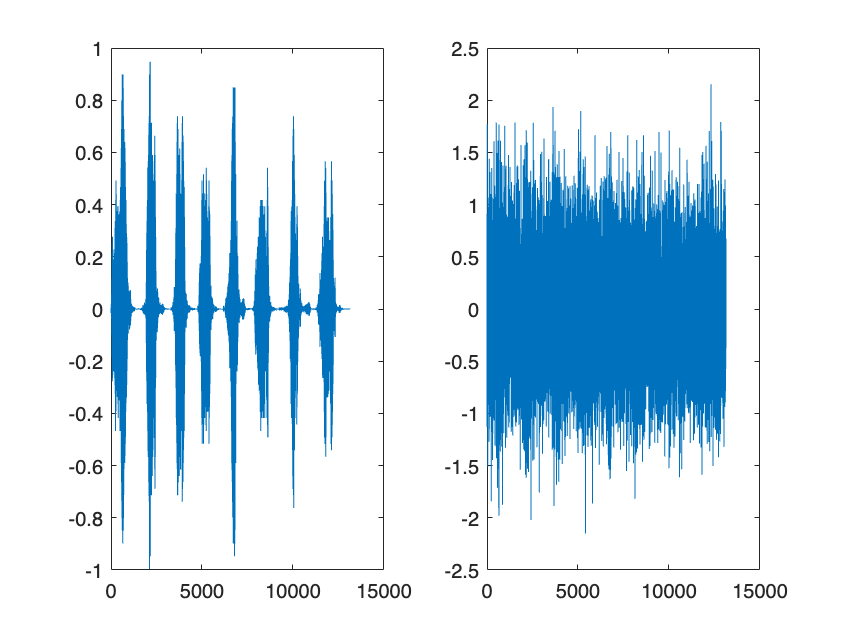

load chirp
y0=y;
noise =0.5*randn(size(y));
Fs = 8919;

yw_ask2 = y0 + noise;

figure
subplot(121);plot(y0)
subplot(122);plot(yw_ask2)

#### Το Αρχικό μας Σήμα

% sound(y, Fs)

#### Το Σήμα μας με Θόρυβο

% sound(yw_ask2, Fs)

### Δημιουργία Φίλτρων 

NumFFT = 4096;
F = linspace(-Fs/2,Fs/2,NumFFT);

#### fir1(.)

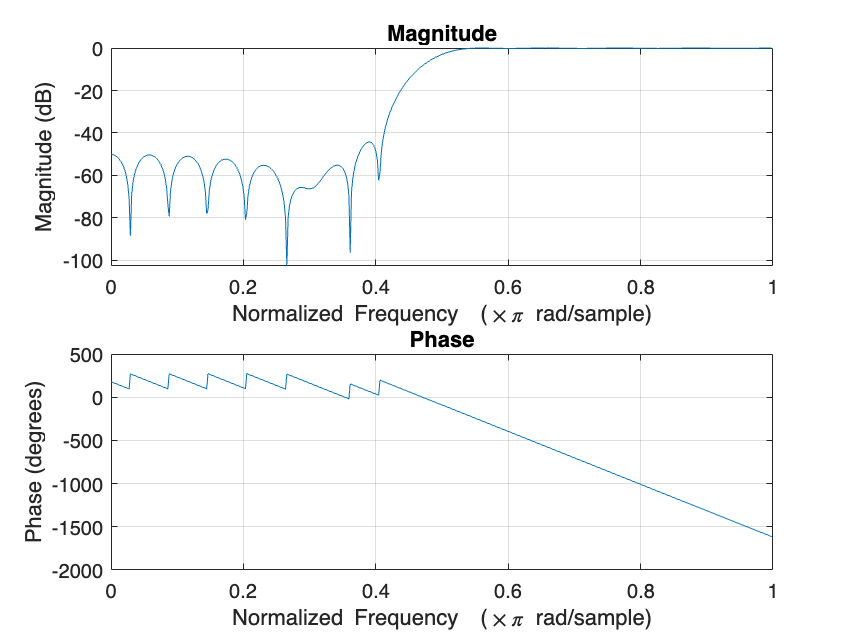


b1 = fir1(34,0.48,'high',chebwin(35,30));

figure
freqz(b1,1,512);


yf1 = filtfilt(b1,1,yw_ask2);

% sound(yf1, Fs)

#### firls(.)

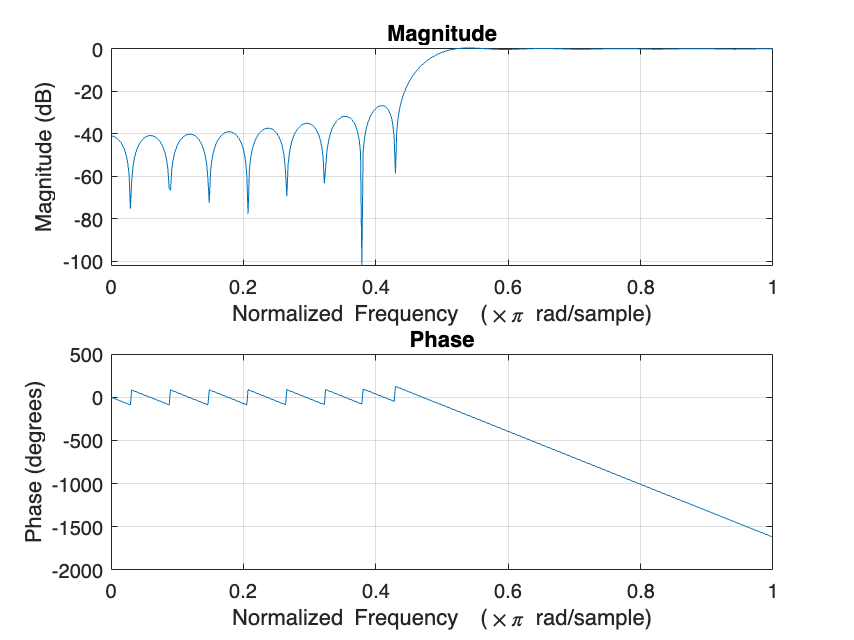

b2 = firls(34,[0, 0.45, 0.5, 1] , [0 0 1 1]);

figure
freqz(b2,1,512);


yf2 = filtfilt(b2,1,yw_ask2);

% sound(yf2, Fs)

#### firpm(.)

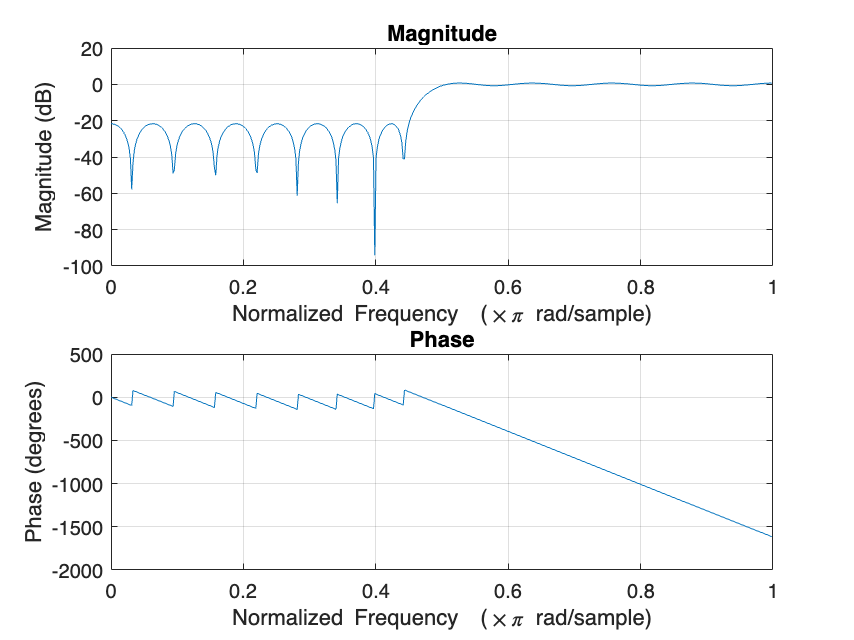

b3 = firpm(34,[0, 0.45, 0.5, 1] , [0 0 1 1]);

figure
freqz(b3,1,512);


yf3 = filtfilt(b3,1,yw_ask2);

% sound(yf3, Fs)

### Αποκρύσεις Συχνότητας Φίλτρων 

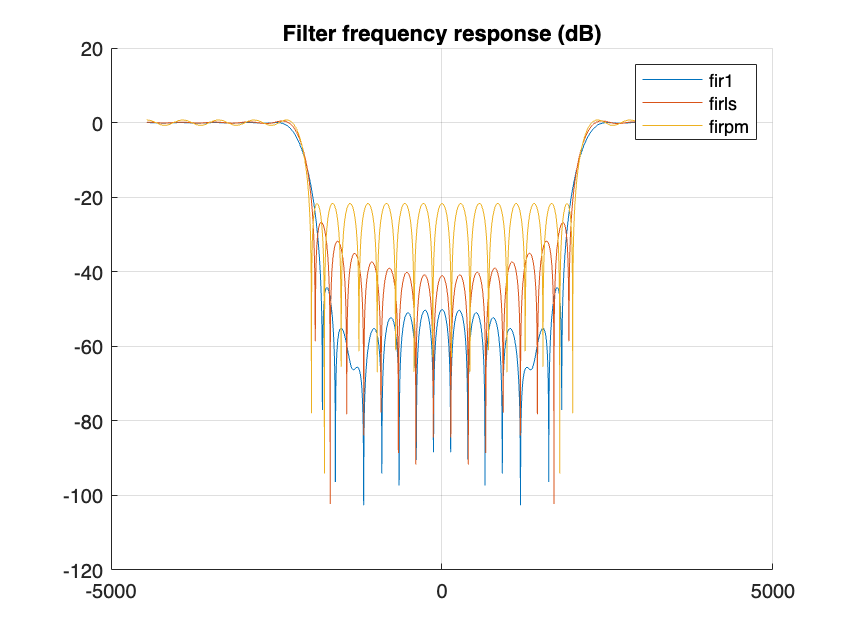

figure
title('Filter frequency response (dB)')

hold on
plot(F, 20*log10(abs(fftshift(fft(b1,NumFFT)))));
plot(F, 20*log10(abs(fftshift(fft(b2,NumFFT)))));
plot(F, 20*log10(abs(fftshift(fft(b3,NumFFT)))));
legend('fir1','firls','firpm')
hold off
grid on

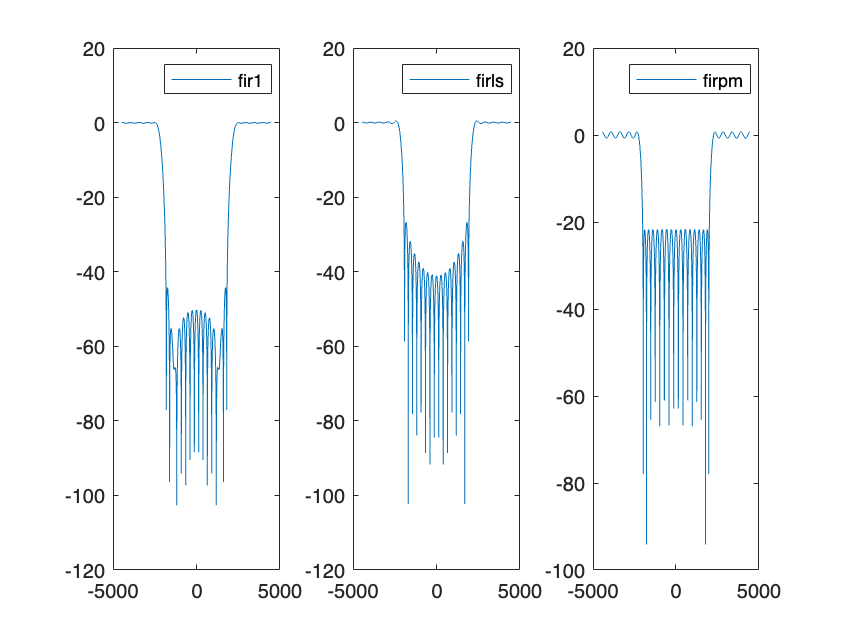





figure
title('Filter frequency response (dB)')

subplot(131);plot(F, 20*log10(abs(fftshift(fft(b1,NumFFT)))));
legend('fir1')

subplot(132);plot(F, 20*log10(abs(fftshift(fft(b2,NumFFT)))));
legend('firls')

subplot(133);plot(F, 20*log10(abs(fftshift(fft(b3,NumFFT)))));
legend('firpm')

### Το Αποθορυβοποιημένο Σήμα

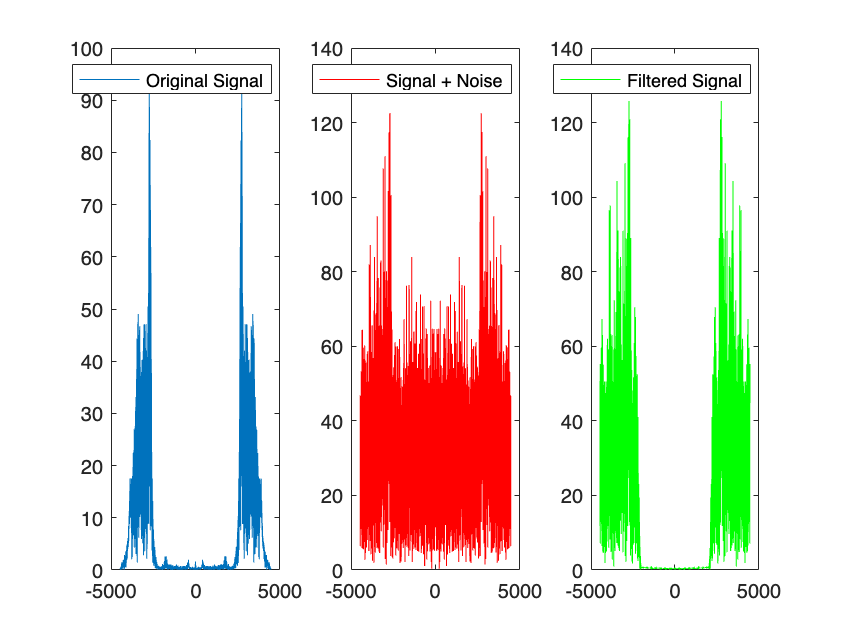


figure
subplot(131);plot(F, abs(fftshift(fft(y0,NumFFT))))
legend('Original Signal')

subplot(132);plot(F, abs(fftshift(fft(yw_ask2,NumFFT))),'r')
legend('Signal + Noise')

subplot(133);plot(F, abs(fftshift(fft(yf3,NumFFT))),'g')
legend('Filtered Signal')

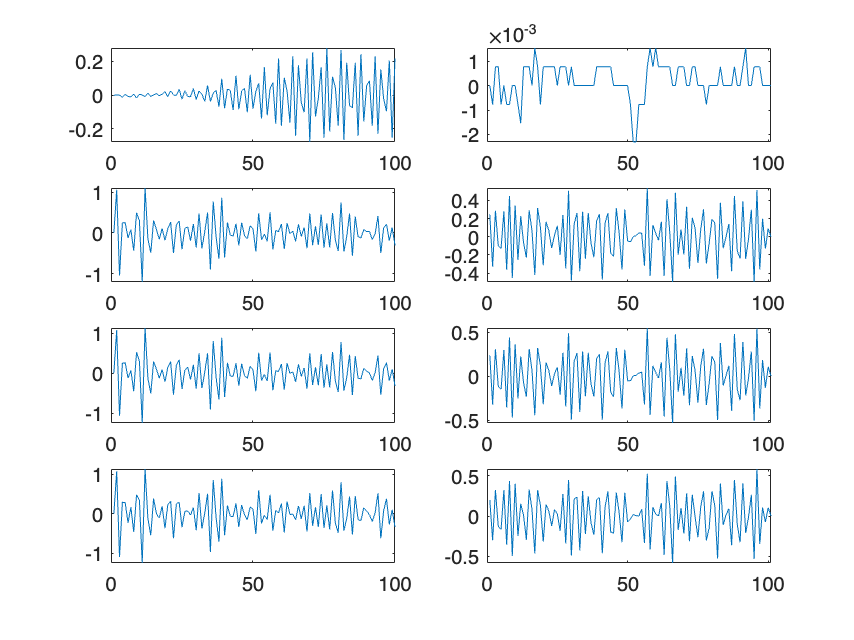



figure

subplot(421); plot(y0(1:100))
subplot(422); plot(y0(end-100:end))

subplot(423); plot(yf1(1:100))
subplot(424); plot(yf1(end-100:end))

subplot(425); plot(yf2(1:100))
subplot(426); plot(yf2(end-100:end))

subplot(427); plot(yf3(1:100))
subplot(428); plot(yf3(end-100:end))

### Απόδοση Φίλτρων 

r1 = y0-yf1;
r2 = y0-yf2;
r3 = y0-yf3;

MSE = [mean(r1.^2) mean(r2.^2) mean(r3.^2) ]

MSE =     0.1118    0.1200    0.1244


## Άσκηση 3

### Το Σήμα μας 

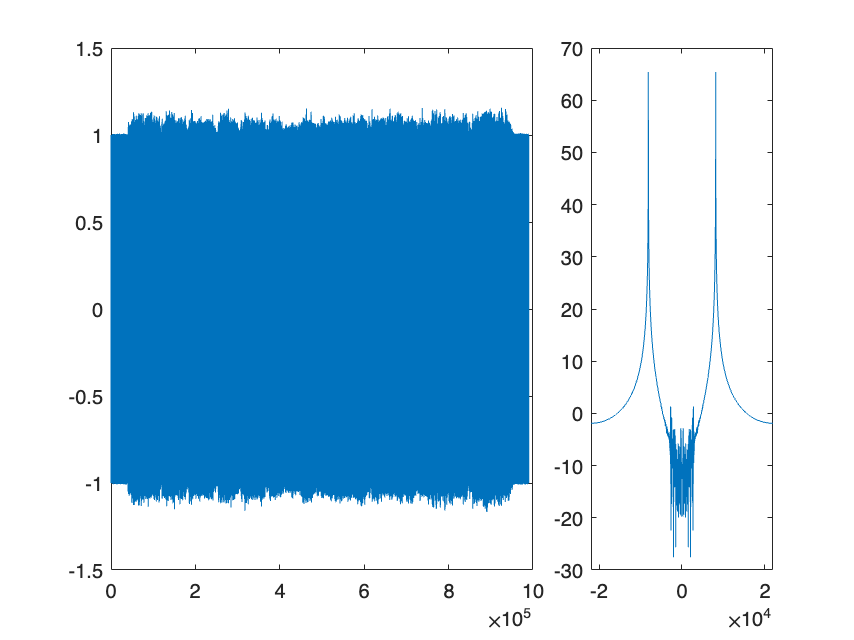

load Noisy.mat
load myfilter.mat
NumFFT = 4096;

Freqs = linspace(-Fs/2,Fs/2,NumFFT);

figure
subplot(1, 3, 1:2); plot(yw)
subplot(1, 3, 3); plot(Freqs,20*log10(abs(fftshift(fft(yw,NumFFT)))))

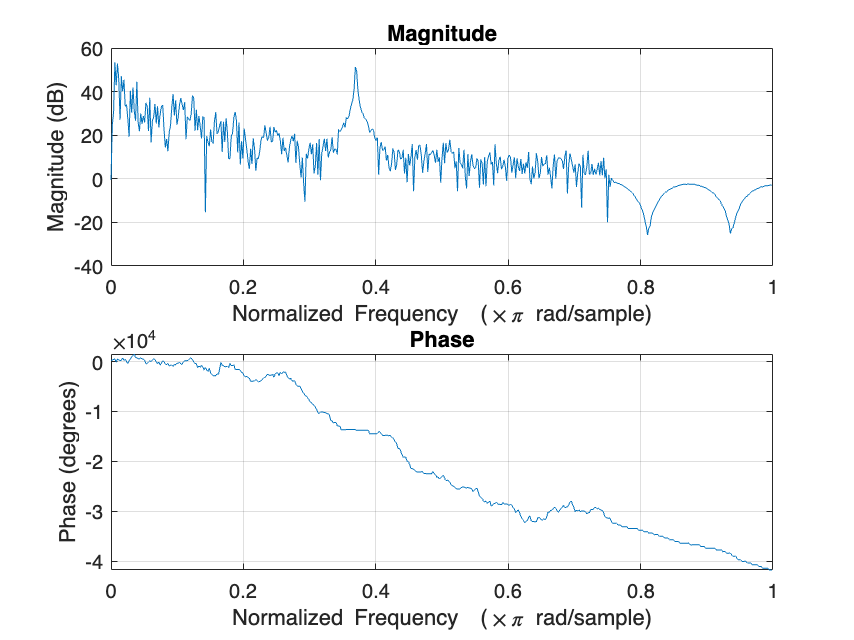


figure
freqz(yw)

### Δημιουργία και εφαρμογή Φίλτρου

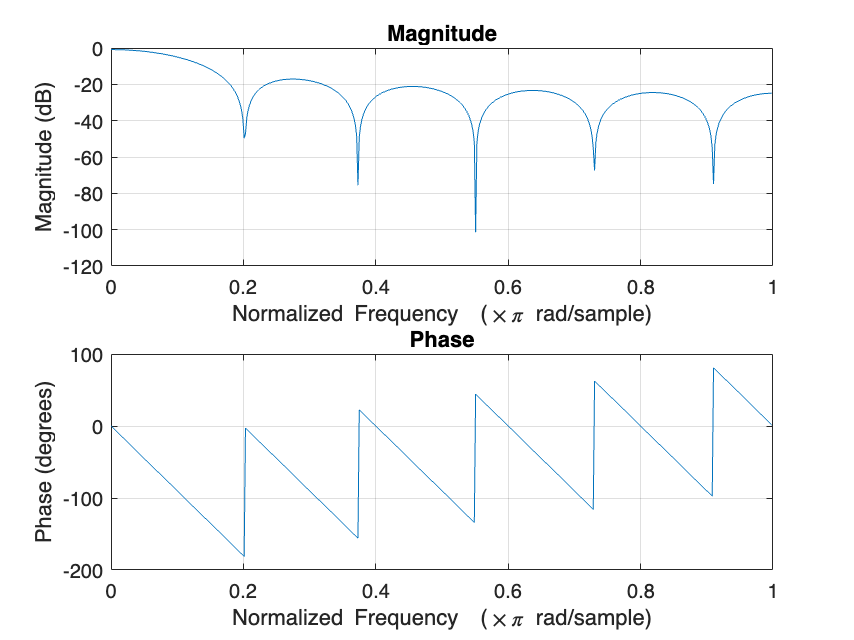

filtered = filtfilt(myfilter,1,yw);
freqz(myfilter);

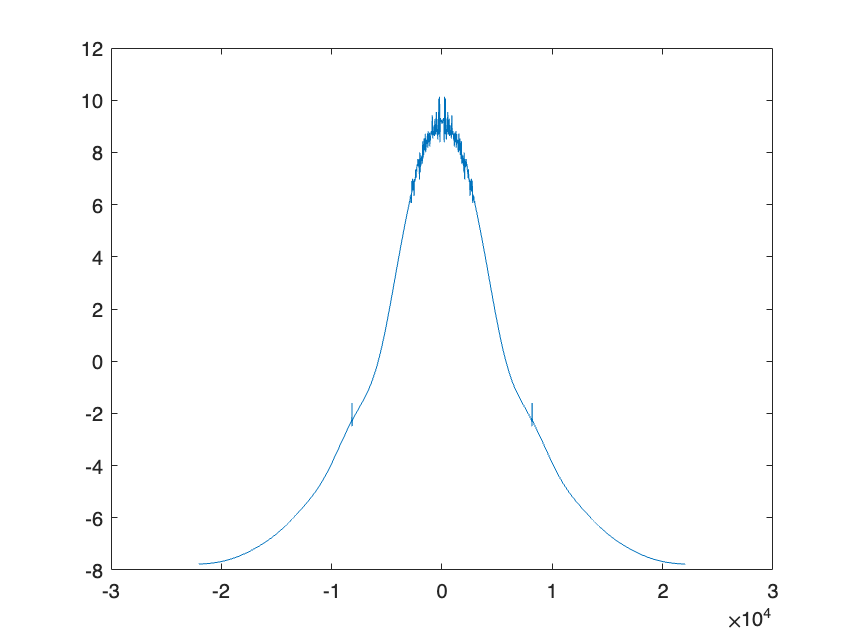


figure
plot(Freqs,20*log10(abs(fftshift(fft(filtered,NumFFT)))));


sound(filtered,Fs);


### Απομόνωση θορύβου

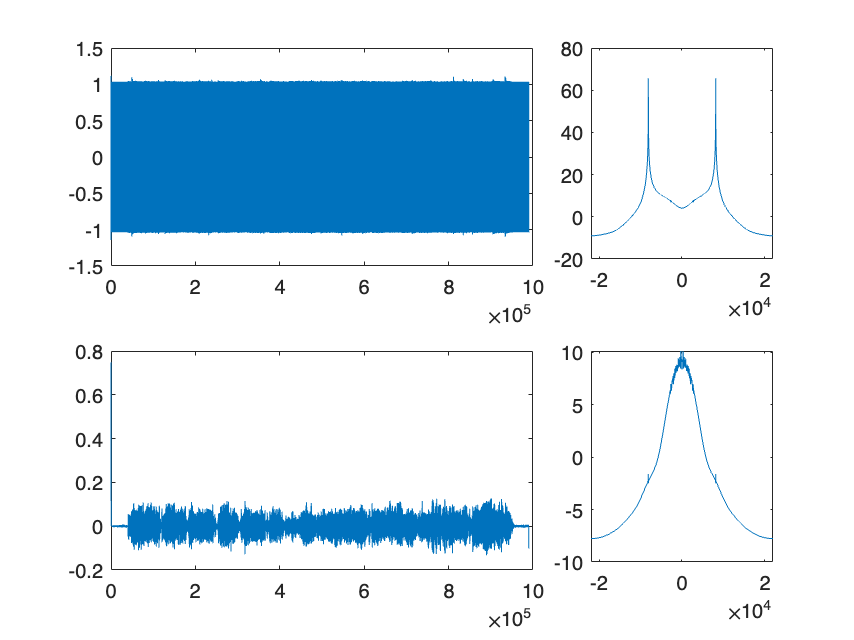

load inverse_filter.mat
noise = filtfilt(inversefilter,1,yw);

figure
subplot(2,3,1:2);plot(noise);
subplot(2,3,3);plot(Freqs,20*log10(abs(fftshift(fft(noise,NumFFT)))));

subplot(2,3,4:5);plot(filtered);
subplot(2,3,6);plot(Freqs,20*log10(abs(fftshift(fft(filtered,NumFFT)))));

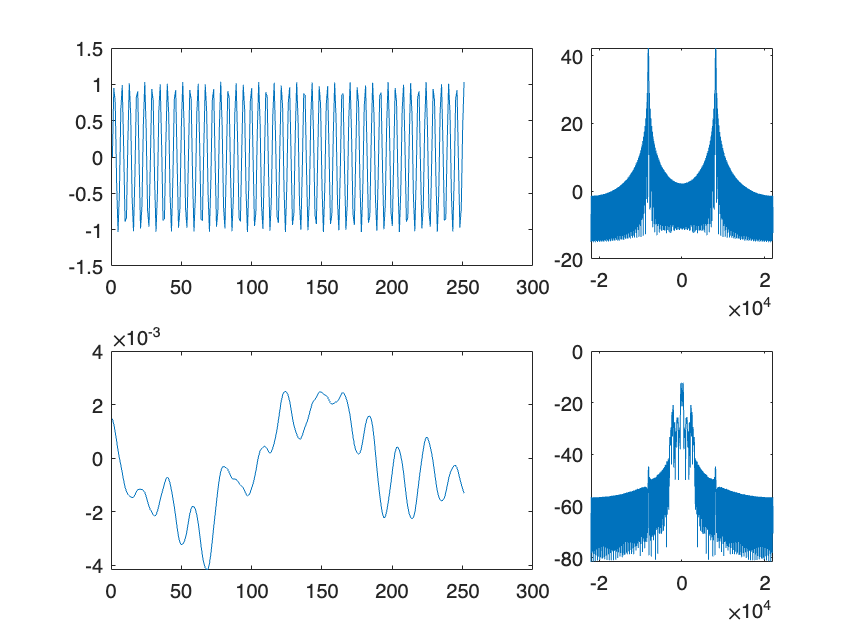



figure
subplot(2,3,1:2);plot(noise(10000:10250));
subplot(2,3,3);plot(Freqs,20*log10(abs(fftshift(fft(noise(10000:10250),NumFFT)))));

subplot(2,3,4:5);plot(filtered(10000:10250));
subplot(2,3,6);plot(Freqs,20*log10(abs(fftshift(fft(filtered(10000:10250),NumFFT)))));